## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

rng(7) % 5 seems to be the ideal case

%% Create a network object
network_index = 0;                  % network Index
numOfPlatoons = 3;                  % num of platoons
numOfVehicles = [4,5,6];            % num of vehicles in each platoon

totalNumOfVehicles = sum(numOfVehicles);
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

% Define the initially vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration
vehiclePositionDesired = 0;         % Desired zeroth vehicle position
vehicleVelocityDesired = 2;         % Desired zeroth vehicle velocity
vehicleAccelerationDesired = 0;     % Desired zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

%-----------------------------------------------------------------------------------------------
% In this loop, we define the initial states/desired states for
% all the vehicles in different platoons
%-----------------------------------------------------------------------------------------------
for k = 1:1:numOfPlatoons       % for every platoon
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    des_states_k =  [];                   % desired signals to be tracked collection
        
    for i = 1:1:numOfVehicles(k)   % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        des_states_k =  [des_states_k, des_state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean -...
            vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        
        
        % Desired vehicular position/velocity/acceleration profile
        vehiclePositionDesired = vehiclePositionDesired - vehicleSeperationMean;
        vehicleVelocityDesired = 2;
        vehicleAccelerationDesired = 0;
        des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % noise parameters
        noisemean_ki = rand(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    vehiclePositionDesired = des_states_k(1,end) - platoonSeperationMean;
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

    parameters{k} = parameters_k;
    states{k} = states_k;
    des_states{k} = des_states_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

%-----------------------------------------------------------------------------------------------

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,...
    states,des_states,noiseMean,noiseStd)    %task 1

net =   Network with properties:

     networkIndex: 0
    numOfPlatoons: 3
    numOfVehicles: [4 5 6]
         platoons: [1×3 Platoon]
             time: 0
            error: 0
             cost: 0
         graphics: []


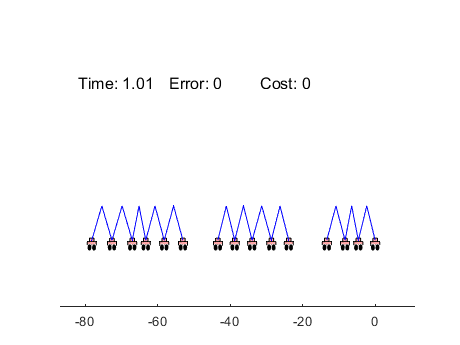

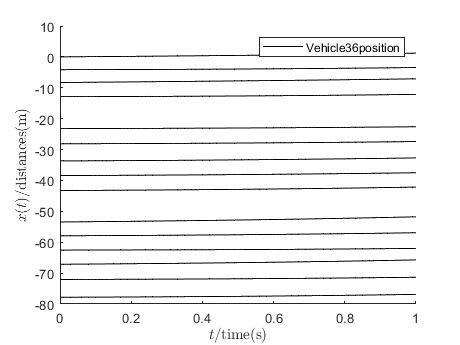



% Plot the platoons
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)


% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 1;
yLow = -10;
yMax = 10;

for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        positions{k,i} = [];
    end
end

for t = 0:dt:tMax
    % Vehicular states update
    for k = 1:1:numOfPlatoons
        for i = 1:1:numOfVehicles(k)
            positions{k,i} = net.platoons(k).vehicles(i).states(1);
        end
    end  

    % Use this update function to achieve the update of the entire program
    net.update(dt)
    net.redrawNetwork(1)
%     if t > 0
%         figure(2)
%         hold on
%         positions{1,2} = [positions{1,2}, net.platoons(1).vehicles(2).states(1)];
%         plot([t-dt,t],positions{1,2},'-k')      %task 4: plotting errors
%         xlabel('$t$/time(s)','Interpreter','latex')
%         ylabel('$x(t)$/distances(m)','Interpreter','latex')
%     end
    for k = 1:1:numOfPlatoons
        for i = 1:1:numOfVehicles(k)
            if t > 0
                figure(2)
                hold on
                plot([t-dt,t],[positions{k,i}, net.platoons(k).vehicles(i).states(1)],...
                    '-',...
                    'Color', [0, 0, 0])      %task 4: plotting errors
                legend(['Vehicle',num2str(k),num2str(i),'position'])
                xlabel('$t$/time(s)','Interpreter','latex')
                ylabel('$x(t)$/distances(m)','Interpreter','latex')
%                 axis([0,tMax,yLow,yMax]);
            end
        end
    end    
    pause(0.001)
    
end

close all;

% length = 2.5;
% height1 = 0.5;
% height2 = 0.25;
% pos = 10;
% 
% axis equal
% 
% figure(1); hold on;
% poly1 = polyshape([pos,(pos-length),(pos-length),pos],[0.5,0.5,0.5+height1,0.5+height1]+8*(2-1)*[1, 1, 1, 1]);
% plot(poly1,'FaceColor','r')
% poly2 = polyshape([0.5*(pos+0.5*(pos+(pos-length))),0.5*((pos-length)+0.5*(pos+(pos-length))),0.5*((pos-length)+0.5*(pos+(pos-length))),0.5*(pos+0.5*(pos+(pos-length)))],...
%     [0.5+height1,0.5+height1,(0.5+height1)+height2,(0.5+height1)+height2]+8*(2-1)*[1, 1, 1, 1]);
% plot(poly2,'FaceColor','r')
% 
% viscircles([0.5*((pos-length)+0.5*(pos+(pos-length))), 0.3+8*(2-1)], 0.3,'Color','k');
% viscircles([0.5*(pos+0.5*(pos+(pos-length))), 0.3+8*(2-1)], 0.3,'Color','k');
% axis equal
% axis([x1,x2,0,10])